# Metody optymalizacji - moduł 5

# Zadanie 1

clc
clear

Definicje funkcji i ich pochodnych

fun1 = @(x) 20*x.^2 - 44*x + 29;
fun1p = @(x) 40*x - 44;
fun2 = @(x) 40*x.^3 + fun1(x);
fun2p = @(x) 120*x.^2 + fun1p(x);

Parametry

alfa = 0.4;
beta = 0.9;
start = 1;

rysowanie

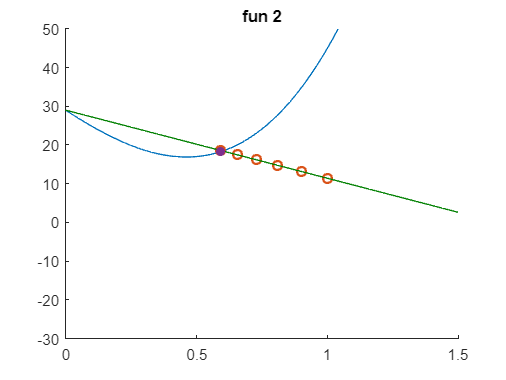

hold on
do_and_draw_backtrack_search(0, 2.5, fun2, fun2p, alfa, beta, start, [0 1.5 -30 50])
title('fun 2');

### TODO:

narysować ładne wykresy

function [s, history] = backtracking_search(fun, funp, alfa, beta, start)
    s = start;
    history = s;
    while fun(s) >= fun(0) + alfa * funp(0)*s
        s = beta * s;
        history = [history s];
    end
end

function do_and_draw_backtrack_search(x_min, x_max, fun, funp, alfa, beta, start, ...
    graph_limits)

X = linspace(x_min, x_max, 100);

plot(X, fun(X));
[~, history] = backtracking_search(fun, funp, alfa, beta, start);

l = @(x, a) fun(0) + a * funp(0) * x;
scatter(history, l(history, alfa), 'LineWidth', 1.5, 'Color', 'black');
plot(X, l(X, alfa), 'Color', [0 0.5 0]);
scatter(history(end), fun(history(end)), 'filled', 'Color', 'red')

axis(graph_limits);

end